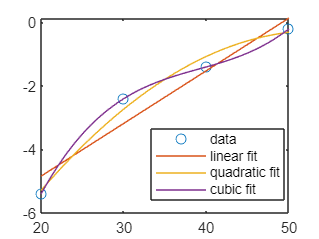

zeta = [20 30 40 50];
conductivity = [8 23 28 34];
b = (conductivity - 35) ./ 5;

% linear fit
A_lin = cat(2, ones(1, 4)', zeta');
A_star_lin = A_lin' * A_lin;
b_star_lin = A_lin' * b';
coefs_lin = (inv(A_star_lin) * b_star_lin)';

% quadratic fit
A_quad = cat(2, ones(1, 4)', zeta', (zeta.^2)');
A_star_quad = A_quad' * A_quad;
b_star_quad = A_quad' * b';
coefs_quad = (inv(A_star_quad) * b_star_quad)';

% cubic fit
A_cub = cat(2, ones(1, 4)', zeta', (zeta.^2)', (zeta.^3)');
A_star_cub = A_cub' * A_cub;
b_star_cub = A_cub' * b';
coefs_cub = (inv(A_star_cub) * b_star_cub)';

% plotting
x = 20:50;
plot(zeta, b, "-o", LineStyle="none");
hold on;
plot(x, coefs_lin(1) + coefs_lin(2) .* x);
plot(x, coefs_quad(1) + coefs_quad(2) .* x + coefs_quad(3) .* (x .^ 2));
plot(x, coefs_cub(1) + coefs_cub(2) .* x + coefs_cub(3) .* (x .^ 2) + coefs_cub(4) .* (x .^ 3));
legend("data", "linear fit", "quadratic fit", "cubic fit", Location="best");